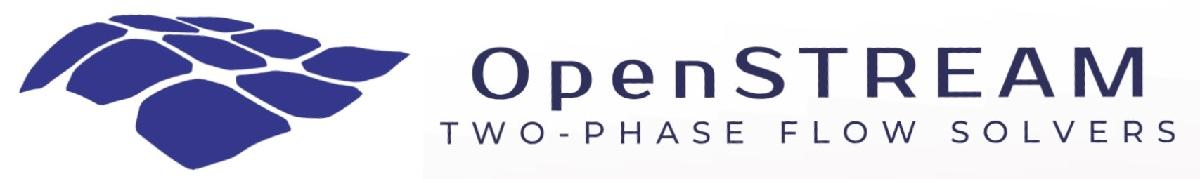

# Tutorial #1: Basic capabiltitie and functionalities

## Introduction

Welcome to OpenSTREAM!

This tutorial will demonsrate basic capabiltitie and functionalities of the code, applied to all four solvers.

The geometry being investigated is a 3.5 m uniformly heated tube, with an additional 2 m adiabatic. 

The liquid flow enters slightly subcooled, transitoning to annular two-phase flow at about 0.7 m and film dryout at end of heated length (3.5 m).

Along the adiabtic section, liquid droplet deposit to the wall toward fully developped annular two-phase flow.

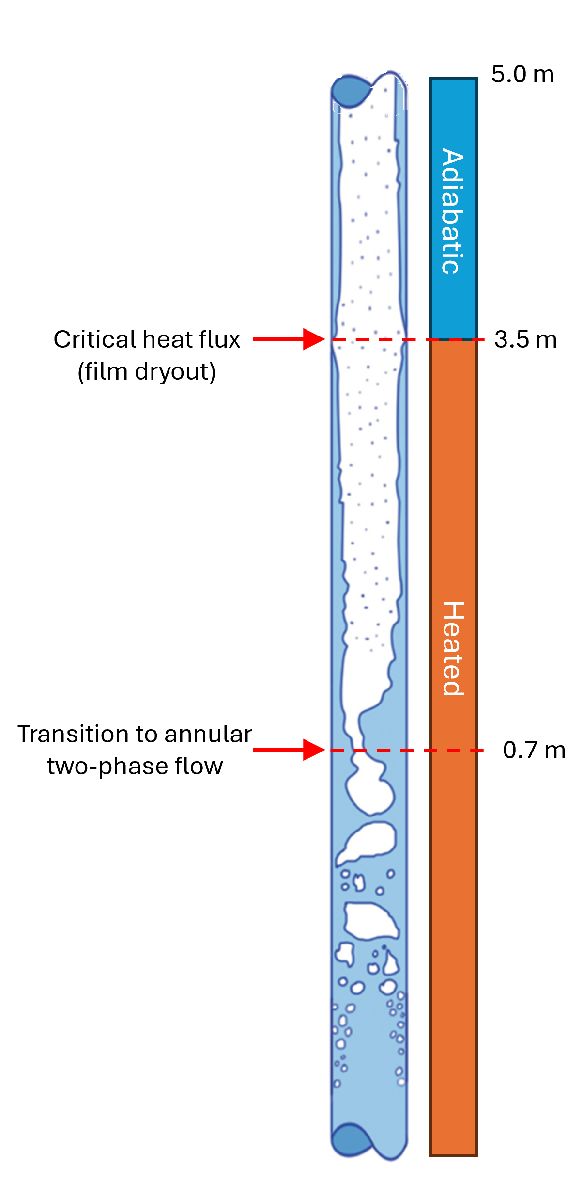

*Before running this tutorial, make sure that OpenSTREAM is in the MATLAB search path.*

All necessary input files are provided in folder inputs/

## Mixture solver

In this section, basic use of the mixture solver will be demonstrated.

We first start by adding the mixture solver class to the import list. 

import Inputs.*
import Solvers.*
import Solvers.Mixture.*

The path to the models, options, geometry and boundary condition files are provided, along with the selected IDs.  These paths would need to be modified, depending on your working directory and file locations.

The warning on/off command is used to avoid the code to print all default values for input parameters not specified as input.

warning off
inputSet = InputSet( ...
            modelFilePath         = './inputs/models.inp' , modelID    = 'TUTORIAL1', ...
            optionsFilePath       = './inputs/options.inp', optionsID  = 'DEFAULT'  , ...
            geometryFilePath      = './inputs/geom.inp'   , geometryID = 'TUTORIAL1', ...
            bcFilePath            = './inputs/bc_tutorial1.inp', ...
            sessionParentDir      = fullfile(pwd,'outputs')    , ...
            overwriteSessionFiles = true                       , ...
            LOGMODE               = 'BOTH');        % Use LOGTOFILEONLY for (almost) no print ouptut
warning on

The mixture solver object, mixSolver, is created from the input set.

mixSolver = MixtureSolver(inputSet);

The mixture solver object is initialized at construction. Here, it is explicitly initialized for clarity.

mixSolver.initializeSolver(); 

The solve method is called (does not accept any input argument), solving the flow fields. To reach a steady-state, the solver runs a null transient with large time step, up to convergence.

mixSolver.solve();

We can now look at the code outputs. For instance, the solved void fraction can be printed from the mixture property

disp(mixSolver.mixture.VF')

For convenience, plotting capabilitites are provided with each OpenSTREAM solver class. A few examples are provided below.

mixSolver.plotz('display','W');

mixSolver.plotz('display','VR');

Results can be saved if desired.

mixSolver.saveResults(saveFormat="MAT");

## Two-fluid solver

In this section, basic use of the two-fluid solver will be demonstrated.

We first start by adding the two-fluid solver class to the import list. 

import Solvers.TwoFluid.*

The input parameters are unchanged, hence the input set does not need to be read again.

The two-fluid solver object, twfSolver, is created from the input set and the solved mixture solver object (otherwise, the mixture solver is run again).

twfSolver = TwoFluidSolver(inputSet, mixSolver);

The solve method is called, solving the flow fields. To reach a steady-state, the solver runs a null transient with large time step, up to convergence.

twfSolver.solve();

We can now look at the code outputs. A few figures are generated below.

twfSolver.plotz('display','W');

twfSolver.plotz('display','VR');

Results can be saved if desired.

twfSolver.saveResults(saveFormat="MAT");

## Three-field solver

In this section, basic use of the three-field solver will be demonstrated.

We first start by adding the two-fluid solver class to the import list. 

import Solvers.ThreeField.*

The input parameters are unchanged, hence the input set does not need to be read again.

The two-fluid solver object, tfSolver, is created from the input set and the solved mixture solver object (otherwise, the mixture solver is run again).

tfSolver = ThreeFieldSolver(inputSet, mixSolver);

The solve method is called, solving the flow fields. To reach a steady-state, the solver runs a null transient with large time step, up to convergence.

tfSolver.solve();

We can now look at the code outputs. A few figures are generated below.

tfSolver.plotz('display','W');

tfSolver.plotz('display','U');

Results can be saved if desired.

tfSolver.saveResults(saveFormat="MAT");

## Four-field solver

In this section, basic use of the two-fluid solver will be demonstrated.

We first start by adding the four-field solver class to the import list. 

import Solvers.FourField.*

The input parameters are unchanged, hence the input set does not need to be read again.

The four-field solver object, ffSolver, is created from the input set and the solved mixture solver object (otherwise, the mixture solver is run again).

ffSolver = FourFieldSolver(inputSet, mixSolver);

The solve method is called, solving the flow fields. To reach a steady-state, the solver runs a null transient with large time step, up to convergence.

ffSolver.solve();

We can now look at the code outputs. A few figures are generated below.

ffSolver.plotz('display','W');

ffSolver.plotz('display','U');

ffSolver.plotz('display','FREQUENCY');

Results can be saved if desired.

ffSolver.saveResults(saveFormat="MAT");